# Data Processing - Capacity

#### 여기서는 배터리 데이타를 기반으로 사용자 패턴을 가지는 데이타를 생성하자.  그러나 어렵다.

- B7의 그래프가 이상하다. 더 낮은 SOC 까지 사용하므로 빨리 죽어야 하는데 더 오래산다.

- C rate 와 온도를 의심했으나 데이타를 보면 온도와 C rate 는 다른 배터리 5,6,7 과 같다.

- 아무래도 다른 요인이 더 있는 것 같으나 데이타에서는 확인 불가능하다.   

- 각 배터리의 초기값의 차이가 있어서 분석이 어렵다.

- 정열을 시도했으나 완만학 선형이 아니라서 어려움이 있다.

#### 전체 배터리 테이타를 모두 그려서 사용가능한 데이타를 찾자.

B5

- 기준이 되는 배터리

B6

- B5와 대비해서 cut off voltage 가 낮으므로 SOH가 빨리 줄어든다.

B7 

- 실제 그래프가 이상하다 B0007 이 가장 빨리 daed 라인에 걸쳐야 하나 초기 Capacity가 높아서 분석하기 힘들다.

- discarge voltage 는 시나리오 마다 다르며 NASA 에서는 CC 로 전류소모 2.7볼트에서 cutfoff 

- 따라서 ageing 에 따라 capacity 가 떨어지고 2.7볼트로 떨어지는 시간이 빨라진다.

- B007이 오래가는 이유 : 배터리특성. cutoff voltage 가 중요한 것이 아니라 그 시간이 중요하다. 이것을 결국 용량이다.

- 그런데 이것은 더 시간이 길다. 그러므로 B0005 보다 오래 가는 이상한 결과를 보여준다.

- 따라서 분석 대상에서 제외

 B18

- 배터리 5,6,7 과 다른 사이클 시간을 갖는다. 따라서 위 3개 배터리와 다른 조건에서 테스트가 진행되었다.

## Capacity 

## Dataset

Data Description:

A set of four Li-ion batteries **(# 5, 6, 7 and 18**) were run through 3 different operational profiles (charge, discharge and impedance) **at room temperature (ryan - 데이타에서는 24 degree C로 표시)**. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at a constant current (CC) level of 2A until the battery voltage fell to** 2.7V, 2.5V, 2.2V and 2.5V** for batteries 5 6 7 and 18 respectively. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. Repeated charge and discharge cycles result in accelerated aging of the batteries while impedance measurements provide insight into the internal battery parameters that change as aging progresses. The experiments were stopped when the batteries reached end-of-life (EOL) criteria, which was a 42% fade in rated capacity (from 2Ahr to 1.4Ahr). This dataset can be used for the prediction of both remaining charge (for a given discharge cycle) and remaining useful life (RUL).

Data Description:

A set of three Li-ion batteries **(# 33, 34 and 36)** were run through 3 different operational profiles (charge, discharge and impedance) at room temperature **(24 deg C)**. Charging was carried out in a constant current (CC) mode at 1.5A until the battery voltage reached 4.2V and then continued in a constant voltage (CV) mode until the charge current dropped to 20mA. Discharge was carried out at **4A **until the battery voltage fell to 2.0V and 2.2V for batteries 33 and 34 respectively.** For battery 36 discharge was done at 2A until voltage fell to 2.7V**. Impedance measurement was carried out through an electrochemical impedance spectroscopy (EIS) frequency sweep from 0.1Hz to 5kHz. The experiments were carried out until the capacity had reduced to 1.6Ahr (20% fade).

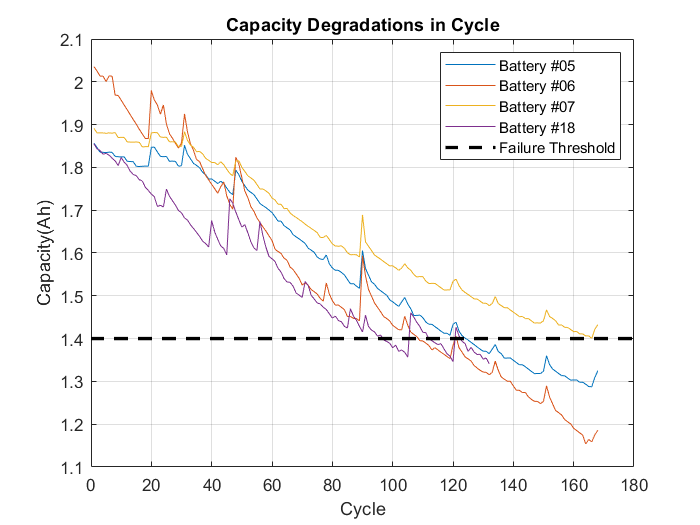

clear % 이전 그래프는 지우지 않는다.
close all %  이전 그래프는 지운다.

% dischage cycle , select capacity
% constant current (CC) level of 2A 
% until the battery voltage fell to 2.7V, 2.5V, 2.2V and 2.5V for batteries 5 6 7 and 18 respectively.
% DOD 가 높을수록 ( #7 ) Capacity 가 근방 줄어든다.

% 배터리 5,6,7은 사용자 패턴이 CC로 더 오래 사용하는가로 설명될 수 있다.


% https://stackoverflow.com/questions/7602816/notepad-incrementally-replace

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

load B0025.mat
load B0026.mat
load B0027.mat
load B0028.mat

load B0029.mat
load B0030.mat
load B0031.mat
load B0032.mat

load B0033.mat
load B0034.mat
load B0036.mat

load B0038.mat
load B0039.mat
load B0040.mat

load B0041.mat
load B0042.mat
load B0043.mat
load B0044.mat

load B0045.mat
load B0046.mat
load B0047.mat
load B0048.mat

load B0049.mat
load B0050.mat
load B0051.mat
load B0052.mat

load B0053.mat
load B0054.mat
load B0055.mat
load B0056.mat

%{
% 읽기 실패
load B0125.mat
load B0126.mat
load B0127.mat
load B0128.mat
%}

%% 

cap05  = extract_discharge( B0005  );
cap06  = extract_discharge( B0006  );
cap07  = extract_discharge( B0007  );
cap18  = extract_discharge( B0018  );

cap25  = extract_discharge( B0025  );
cap26  = extract_discharge( B0026  );
cap27  = extract_discharge( B0027  );
cap28  = extract_discharge( B0028  );

cap29  = extract_discharge( B0029  );
cap30  = extract_discharge( B0030  );
cap31  = extract_discharge( B0031  );
cap32  = extract_discharge( B0032  );

cap33  = extract_discharge( B0033  );
cap34  = extract_discharge( B0034  );
cap36  = extract_discharge( B0036  );

cap38  = extract_discharge( B0038  );
cap39  = extract_discharge( B0039  );
cap40  = extract_discharge( B0040  );

cap41  = extract_discharge( B0041  );
cap42  = extract_discharge( B0042  );
cap43  = extract_discharge( B0043  );
cap44  = extract_discharge( B0044  );

cap45  = extract_discharge( B0045  );
cap46  = extract_discharge( B0046  );
cap47  = extract_discharge( B0047  );
cap48  = extract_discharge( B0048  );

%{
% 실험 소프트웨어가 깨져서 정상 데이타가 들어있지 않다.
cap49  = extract_discharge( B0049  );
cap50  = extract_discharge( B0050  );
cap51  = extract_discharge( B0051  );
cap52  = extract_discharge( B0052  );
%}
cap53  = extract_discharge( B0053  );
cap54  = extract_discharge( B0054  );
cap55  = extract_discharge( B0055  );
cap56  = extract_discharge( B0056  );

%{
% 읽기 실패
cap125 = extract_discharge( B0125 );
cap126 = extract_discharge( B0126 );
cap127 = extract_discharge( B0127 );
cap128 = extract_discharge( B0128 );
%}


figure
plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #05', 'Battery #06', 'Battery #07', 'Battery #18','Failure Threshold')

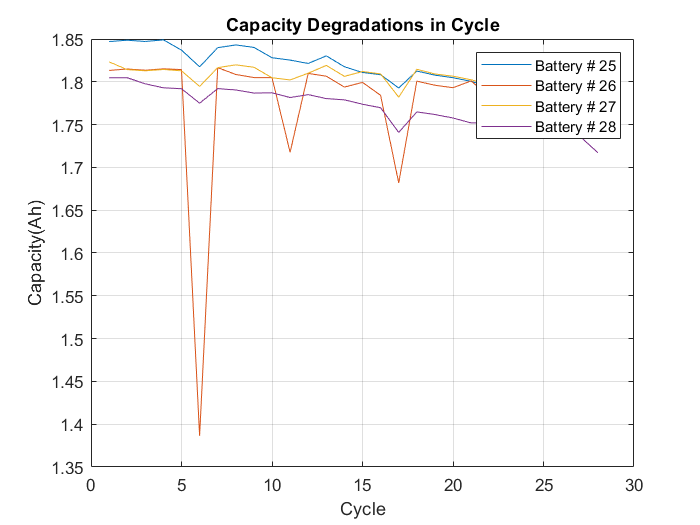

title('Capacity Degradations in Cycle')


figure
plot(cap25), hold on, plot(cap26), plot(cap27), plot(cap28)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 25', 'Battery # 26', 'Battery # 27', 'Battery # 28')

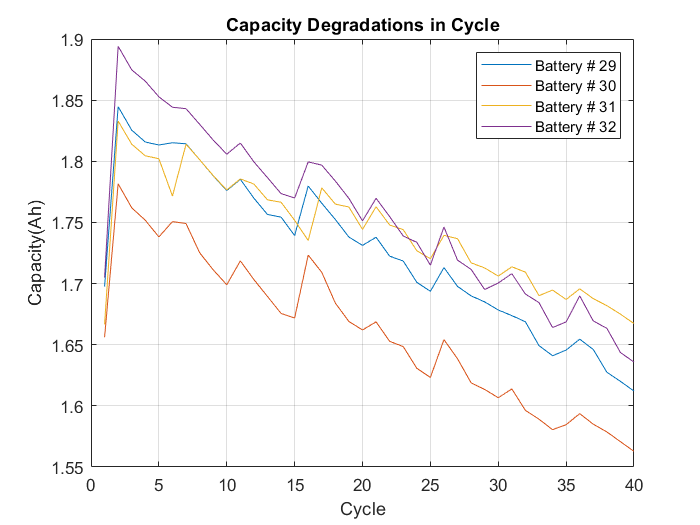

title('Capacity Degradations in Cycle')


figure
plot(cap29), hold on, plot(cap30), plot(cap31), plot(cap32)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 29', 'Battery # 30', 'Battery # 31', 'Battery # 32')

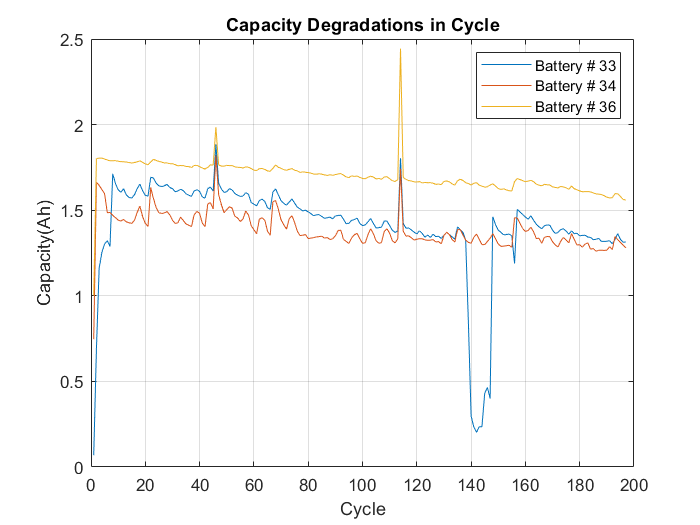

title('Capacity Degradations in Cycle')

figure
plot(cap33), hold on, plot(cap34), plot(cap36)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 33', 'Battery # 34', 'Battery # 36')

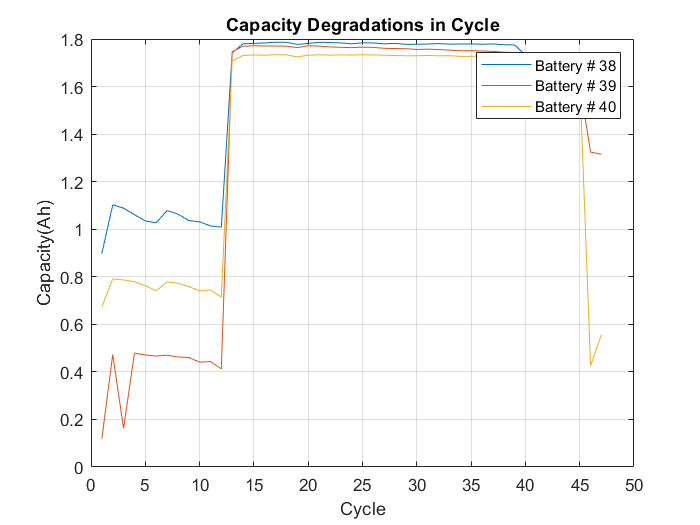

title('Capacity Degradations in Cycle')

figure
plot(cap38), hold on, plot(cap39), plot(cap40)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 38', 'Battery # 39', 'Battery # 40')

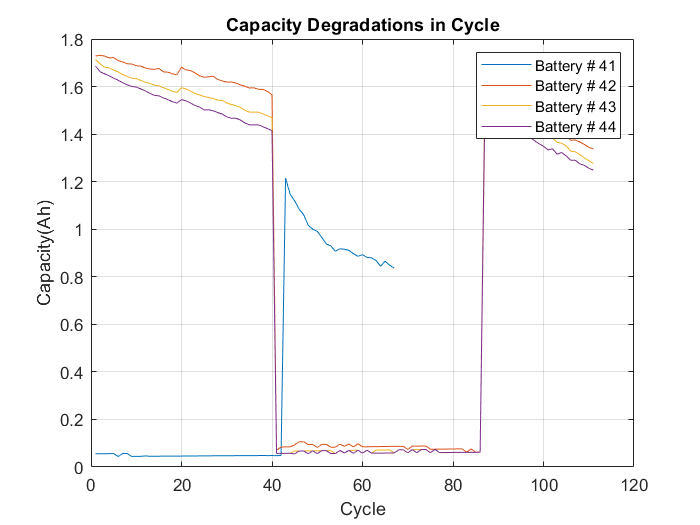

title('Capacity Degradations in Cycle')

figure
plot(cap41), hold on, plot(cap42), plot(cap43), plot(cap44)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 41', 'Battery # 42', 'Battery # 43', 'Battery # 44')

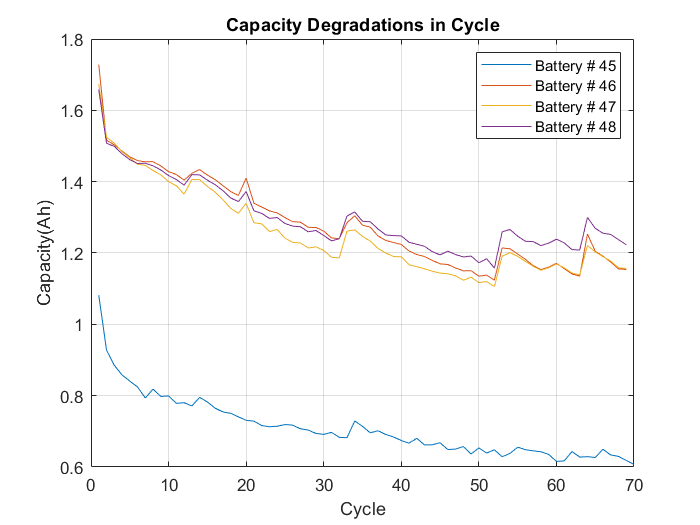

title('Capacity Degradations in Cycle')


figure
plot(cap45), hold on, plot(cap46), plot(cap47), plot(cap48)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 45', 'Battery # 46', 'Battery # 47', 'Battery # 48')

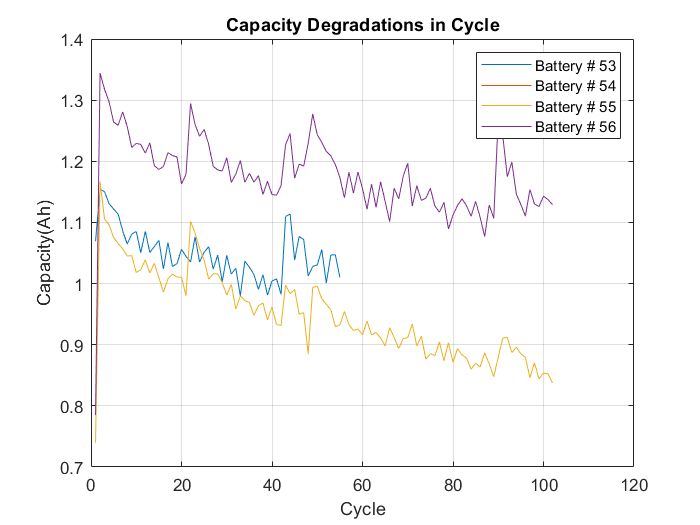

title('Capacity Degradations in Cycle')

%{
figure
plot(cap49), hold on, plot(cap50), plot(cap51), plot(cap51)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 49', 'Battery # 50', 'Battery # 51', 'Battery # 52')
title('Capacity Degradations in Cycle')
%}

figure
plot(cap53), hold on, plot(cap54), plot(cap54), plot(cap56)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 53', 'Battery # 54', 'Battery # 55', 'Battery # 56')

title('Capacity Degradations in Cycle')
%{
figure
plot(cap125), hold on, plot(cap126), plot(cap127), plot(cap128)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery # 125', 'Battery # 126', 'Battery # 127', 'Battery # 128')
title('Capacity Degradations in Cycle')
%}



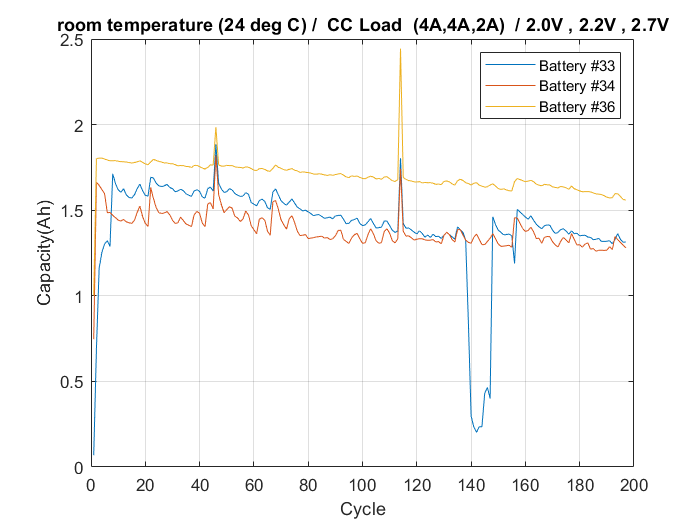

cycleNumber = length(cap33);

figure
plot(cap33), hold on, plot(cap34), plot(cap36)

hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #33', 'Battery #34', 'Battery #36')

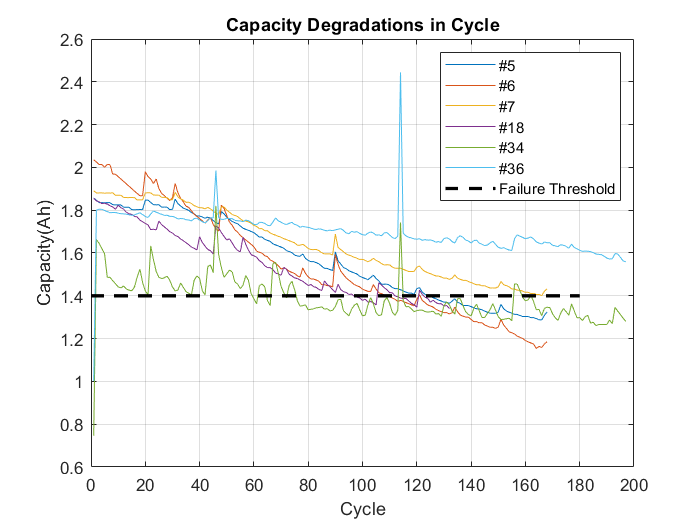

title('room temperature (24 deg C) /  CC Load  (4A,4A,2A)  / 2.0V , 2.2V , 2.7V')
figure
plot(cap05), hold on, plot(cap06), plot(cap07), plot(cap18), plot(cap34), plot(cap36)
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('#5', '#6', '#7', '#18','#34','#36','Failure Threshold')

title('Capacity Degradations in Cycle')
